added_path = [pwd,'\toolbox']

added_path = 'C:\Files\github\Mutational_Signatures\Matlab\wasserstein-dictionary-learning-master\toolbox'

addpath(added_path)

# Wasserstein NMF on histograms representation of mixtures of gaussians

This script is intended as a usage example of the Wasserstein Dictionary Toolbox, it reproduces the experiment in the introduction of [paper]

## Generate the data

ndata=100;              % number of mixtures
niidsample=1000;        % number of sample for each mixture
ndiscretize=100;        % number of histogram bins

minVal=-12;
maxVal=12;
x=linspace(minVal,maxVal,ndiscretize);  % value of the histograms bins

mu=[-6;0;6];                            % mean values for the Gaussians means
shiftVariance=2*eye(3);                 % variance of the Gaussians means
mean=mvnrnd(mu,shiftVariance,ndata)';   % generate the gaussian means
p=rand(3,ndata);                        % generate the mixture weights

sigma=1;                                % variance of the Gaussians

data=zeros(ndiscretize,ndata);          % preallocate memory
for i=1:ndata
    distrib=gmdistribution(mean(:,i),sigma,p(:,i)); % generate a mixture of gaussians distribution
    a=random(distrib,niidsample);                   % sample the distribution
    data(:,i)=hist(a(a>minVal&a<maxVal),x)';        % gather samples in a histogram
end

data=bsxfun(@rdivide,data,sum(data));   % normalize the data

## Visualize the data

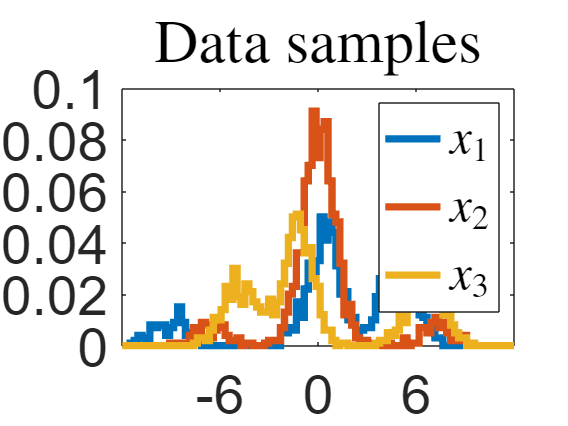

minY=0;
maxY=.1;
YtickStep=.02;
indices=1:3;
fontSize=30;
lineWidth=4;
axisValues=[minVal,maxVal,minY,maxY];


dataLegendArray=cell(numel(indices),1);
for i=1:numel(indices)
    dataLegendArray{i}=['$x_{',num2str(i),'}$'];
end

plotDictionary(x,data(:,indices),axisValues,lineWidth,fontSize,YtickStep,mu,dataLegendArray,'Data samples')

## Build the cost matrix

M=abs(bsxfun(@minus,x',x));
M=M/median(M(:));

## Set the parameters of wasserstein_DL

options.stop=1e-3;
options.verbose=2;
options.D_step_stop=5e-5;
options.lambda_step_stop=5e-4;
options.alpha=0.5;
options.Kmultiplication='symmetric';
options.GPU=0;
k=3;


dictionaryLegendArray=cell(numel(indices),1);
for i=1:k
    dictionaryLegendArray{i}=['$d_{',num2str(i),'}$'];
end

gamma=1/50;

wassersteinOrder=1;

## Perform Wasserstein NMF

rho1=.1;
rho2=.1;
[D, lambda, objectives]=wasserstein_DL(data,k,M.^wassersteinOrder,gamma,rho1,rho2,options);

Optimize with respect to lambda
	Dual iteration : 0 Objective : 19.147297, Current step size 1.000000
		Gradnorm=1.441474 stop=0.000500
	Dual iteration : 1 Objective : 18.433263, Current step size 1.000000
		Gradnorm=1.416768 tol=0.000750
	Dual iteration : 21 Objective : -12.025999, Current step size 0.640000
		Gradnorm=0.624451 tol=0.018719
	Dual iteration : 41 Objective : -17.427384, Current step size 0.262144
		Gradnorm=0.242001 tol=0.027439
	Dual iteration : 61 Objective : -18.012267, Current step size 0.134218
		Gradnorm=0.076940 tol=0.030373
	Dual iteration : 1 Objective : -18.035227, Current step size 0.085899
		Gradnorm=0.025037 tol=0.030524
	Dual iteration : 1 Objective : -18.035227, Current step size 0.096038
		Gradnorm=0.025037 stop=0.030524
Optimize with respect to D
	Dual iteration : 0 Objective : 9.542725, Current step size 1.000000
		Gradnorm=1.388944 stop=0.000050
	Dual iteration : 1 Objective : 8.940555, Current step size 1.000000
		Gradnorm=1.200880 tol=0.000075
	Dual

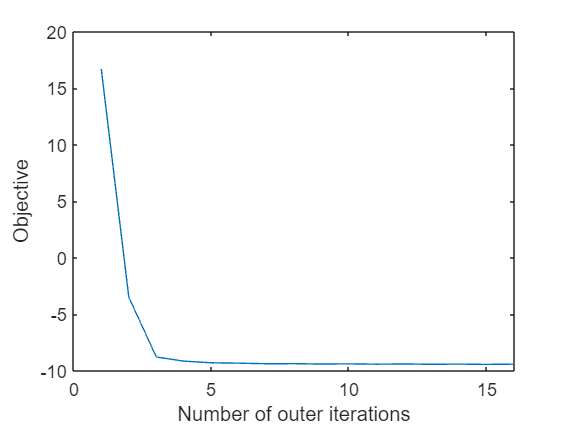


plot(objectives);
xlabel('Number of outer iterations')
ylabel('Objective')

## Visualize the dictionary

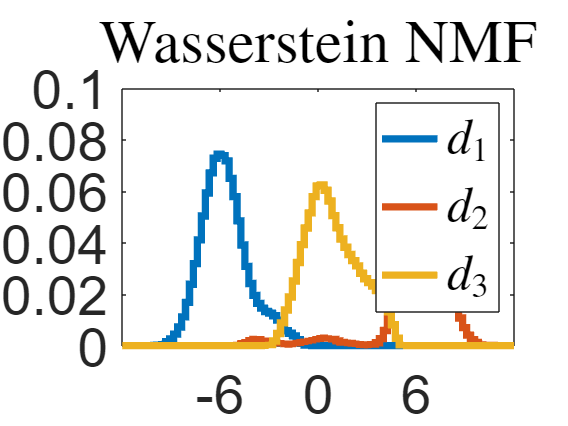

plotDictionary(x,D,axisValues,lineWidth,fontSize,YtickStep,mu,dictionaryLegendArray,'Wasserstein NMF')

## Perform Wasserstein DL

options.alpha=0;
options.D_step_stop=1e-7;
options.lambda_step_stop=1e-7;
[D_DL, lambda_DL, objectives]=wasserstein_DL(data,k,M.^wassersteinOrder,gamma,0,0,options);

Optimize with respect to lambda
    Dual initialization, Objective : 8.1612 Current step size 1
    Dual iteration : 1 Objective : 7.0424 Current step size 1
    Dual iteration : 21 Objective : -16.3788 Current step size 9.3132
    Dual iteration : 41 Objective : -23.0453 Current step size 7.4506
    Dual iteration : 61 Objective : -26.2079 Current step size 4.7684
    Dual iteration : 81 Objective : -27.0257 Current step size 3.0518
    Dual iteration : 101 Objective : -27.213 Current step size 3.0518
    Dual iteration : 121 Objective : -27.344 Current step size 3.0518
    Dual iteration : 141 Objective : -27.4823 Current step size 2.4414
    Dual iteration : 161 Objective : -27.5506 Current step size 2.4414
    Dual iteration : 181 Objective : -27.6015 Current step size 2.4414
    Dual iteration : 201 Objective : -27.6389 Current step size 2.4414
    Dual iteration : 221 Objective : -27.6669 Current step size 2.4414
    Dual iteration : 241 Objective : -27.6895 Current step size 2.4

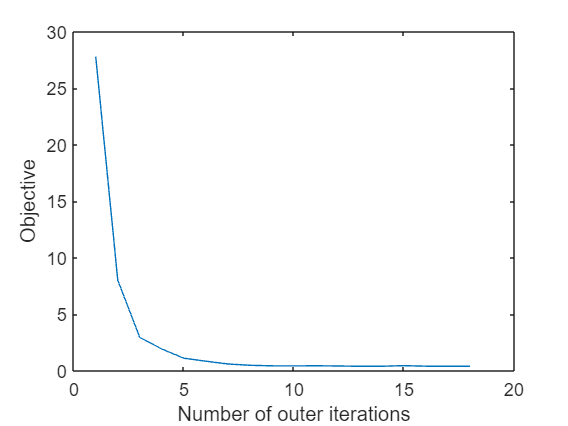

plot(objectives);
xlabel('Number of outer iterations')
ylabel('Objective')

## Visualize the dictionary

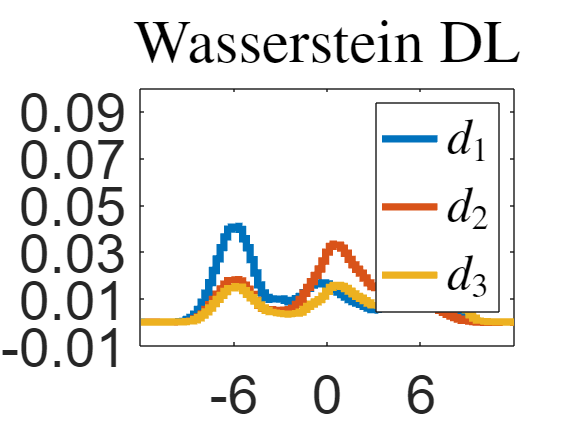

axisValues(3)=floor(min(D_DL(:)*100))/100;

plotDictionary(x,D_DL,axisValues,lineWidth,fontSize,YtickStep,mu,dictionaryLegendArray,'Wasserstein DL')

## Compare data and reconstruction

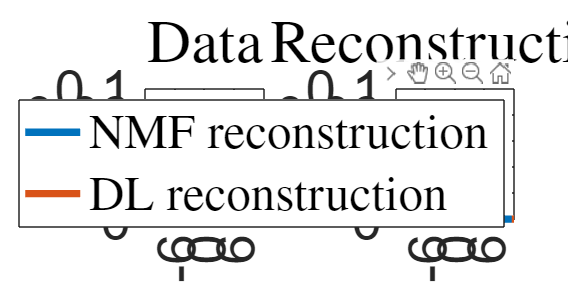

width=1200;
height=600;
figure('Position',[1 1 width height])

axisValues(3)=0;
minY=0;
i=1;

subplot(1,2,1)
plotDictionary(x,data(:,i),axisValues,lineWidth,fontSize,YtickStep,mu,'x','Data')

subplot(1,2,2)
plotDictionary(x,[D*lambda(:,i),D_DL*lambda_DL(:,i)],axisValues,lineWidth,fontSize,YtickStep,mu,{'NMF reconstruction','DL reconstruction'},'Reconstruction')